# 功能：绘制甲烷模型

思路：球的叠加

[Zhihu: https://www.zhihu.com/people/1105936347](https://www.zhihu.com/people/1105936347)

[Github: https://github.com/AFei19911012](https://github.com/AFei19911012)

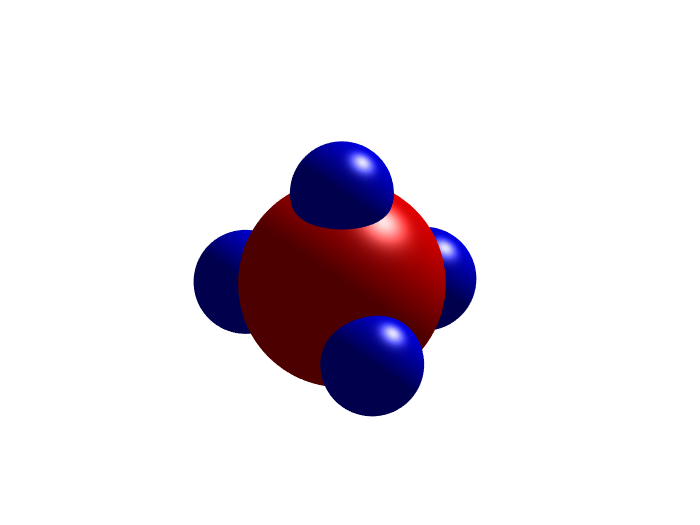

clear;clc;
% 球面的坐标信息，为了看起来平滑一点，给到 100
[x, y, z] = sphere(100);
% C 大小
C = 10; 
% H 大小
H = 5;
% 大球
surf(C*x, C*y, C*z, 'FaceColor', 'red', 'EdgeColor', 'none')
hold on 
% 四个小球，都偏离一点位置，准确的位置需要计算，这里演示一个大概位置
surf(H*x, H*y, H*z + 10, 'FaceColor', 'blue', 'EdgeColor', 'none');
surf(H*x + 10, H*y, H*z - 3, 'FaceColor', 'blue', 'EdgeColor', 'none');
surf(H*x - 4, H*y - 10, H*z - 3, 'FaceColor', 'blue', 'EdgeColor', 'none');
surf(H*x - 4, H*y + 10, H*z - 3, 'FaceColor', 'blue', 'EdgeColor', 'none');
% 坐标轴设置
axis equal off
% 光源，看起来更有立体感
light
lighting gouraud